`Implementation figure 1b isolated vs collective environment`

`This code is associated to code containe din the script ch2RandomWalkImplementation. The only differenc eis the data utilised for the analysis. Here we implement the process of the brightfield data but will be generalized fto the fluorescent data as soosn as the isolated contdition data will be available. `

clear all; close all; clc;
set(0,'DefaultAxesFontSize', 20)

`Start here with the data corresponding to NPR1 `

cd('..')
n = 5;

switch n
    case 1
        filename_col = "/Users/erusconi/Desktop/Brighfield_40&5/Collective(40_worms)/Results/1.1_1_da609_Set0_Pos0_Ch5_14012018_092702_skeletons.hdf5";  
        filename_is = "/Users/erusconi/Desktop/Brighfield_40&5/Isolated(5_Worms)/Results/1.1_1_da609_Set0_Pos0_Ch6_14012018_092702_skeletons.hdf5";     
    case 2
        filename_col = "/Users/erusconi/Desktop/Brighfield_40&5/Collective(40_worms)/Results/1.1_1_eca246_8f_Set0_Pos0_Ch3_14012018_093713_skeletons.hdf5";
        filename_is = "/Users/erusconi/Desktop/Brighfield_40&5/Isolated(5_Worms)/Results/1.1_1_eca246_8f_Set0_Pos0_Ch4_14012018_093713_skeletons.hdf5"; 
    case 3
        filename_col = "/Users/erusconi/Desktop/Brighfield_40&5/Collective(40_worms)/Results/1.1_1_nic252_c2_Set0_Pos0_Ch1_14012018_094825_skeletons.hdf5"; 
        filename_is = "/Users/erusconi/Desktop/Brighfield_40&5/Isolated(5_Worms)/Results/1.1_1_nic252_c2_Set0_Pos0_Ch2_14012018_094825_skeletons.hdf5"; 
    case 4
        filename_col = "/Users/erusconi/Desktop/Brighfield_40&5/Collective(40_worms)/Results/1.1_2_cx11271_cb_Set0_Pos0_Ch3_14012018_104549_skeletons.hdf5"; 
        filename_is = "/Users/erusconi/Desktop/Brighfield_40&5/Isolated(5_Worms)/Results/1.1_2_cx11271_cb_Set0_Pos0_Ch4_14012018_104549_skeletons.hdf5"; 
    case 5
        filename_col = "/Users/erusconi/Desktop/Brighfield_40&5/Collective(40_worms)/Results/1.1_2_ed3040_do_Set0_Pos0_Ch1_14012018_105326_skeletons.hdf5"; 
        filename_is = "/Users/erusconi/Desktop/Brighfield_40&5/Isolated(5_Worms)/Results/1.1_2_ed3040_do_Set0_Pos0_Ch2_14012018_105326_skeletons.hdf5"; 
    case 6
        filename_col = "/Users/erusconi/Desktop/Brighfield_40&5/Collective(40_worms)/Results/1.1_2_ju830_b5_Set0_Pos0_Ch5_14012018_103803_skeletons.hdf5";
        filename_is = "/Users/erusconi/Desktop/Brighfield_40&5/Isolated(5_Worms)/Results/1.1_2_ju830_b5_Set0_Pos0_Ch6_14012018_103803_skeletons.hdf5"; 
    case 7
        filename_col = "/Users/erusconi/Desktop/Brighfield_40&5/Collective(40_worms)/Results/1.1_3_ed3017_c1_Set0_Pos0_Ch1_14012018_120042_skeletons.hdf5"; 
        filename_is = "/Users/erusconi/Desktop/Brighfield_40&5/Isolated(5_Worms)/Results/1.1_3_ed3017_c1_Set0_Pos0_Ch2_14012018_120042_skeletons.hdf5"; 
    case 8
        filename_col = "/Users/erusconi/Desktop/Brighfield_40&5/Collective(40_worms)/Results/1.1_3_my23_6c_Set0_Pos0_Ch5_14012018_114022_skeletons.hdf5"; 
        filename_is = "/Users/erusconi/Desktop/Brighfield_40&5/Isolated(5_Worms)/Results/1.1_3_my23_6c_Set0_Pos0_Ch6_14012018_114022_skeletons.hdf5"; 
    case 9
        filename_col = "/Users/erusconi/Desktop/Brighfield_40&5/Collective(40_worms)/Results/1.1_4_brc20067_9d_Set0_Pos0_Ch5_14012018_125041_skeletons.hdf5"; 
        filename_is = "/Users/erusconi/Desktop/Brighfield_40&5/Isolated(5_Worms)/Results/1.1_4_brc20067_9d_Set0_Pos0_Ch6_14012018_125041_skeletons.hdf5"; 
end 

% Bright field Collective Conditions 
trajData_collective = h5read(filename_col,'/trajectories_data');   %coord_x & coord_y
skeleton_collective = h5read(filename_col,'/skeleton');


% Bright field Isolated Conditions 
trajData_isolated = h5read(filename_is,'/trajectories_data');   %coord_x & coord_y
skeleton_isolated = h5read(filename_is,'/skeleton');


`Clean this up to make it more genralizable when we have multiple strains. `

`Keep only trajectories that are longer then min_length (=100) in both cases `

`worm_index_present contains all the indexes `

`worm_index_kept contains only teh indexes of the worms with a trajectory lonmger then 100 frames `

`row_worm_i containes the rows corresponding to the worm index `

min_length = 100; 
worm_index_present_collective = unique(trajData_collective.worm_index_joined); 
worm_index_present_isolated = unique(trajData_isolated.worm_index_joined); 

worm_index_kept_collective = []; 
row_worm_i_collective = {}; 
 
for i = 1:size(worm_index_present_collective,1)      % loop through each individual 
    row_worm_i_collective = [row_worm_i_collective; find(trajData_collective.worm_index_joined == worm_index_present_collective(i))];  
    worm_index_kept_collective = [worm_index_kept_collective; worm_index_present_collective(i)]; 
    if size(row_worm_i_collective{end},1) < min_length
        row_worm_i_collective(end) = []; 
        worm_index_kept_collective(end) = [];   
    end 
end 


worm_index_kept_isolated = [];
row_worm_i_isolated = {}; 
for i = 1:size(worm_index_present_isolated,1)      % loop through each individual 
    row_worm_i_isolated = [row_worm_i_isolated; find(trajData_isolated.worm_index_joined == worm_index_present_isolated(i))];
    worm_index_kept_isolated = [worm_index_kept_isolated; worm_index_present_isolated(i)]; 
    if size(row_worm_i_isolated{end},1) < min_length
        row_worm_i_isolated(end) = []; 
        worm_index_kept_isolated(end) = [];
    end 
end 


$$\phi \left(t\right):\textrm{bearing}$$


velocity_centrioid_filt_collective = cell(size(worm_index_kept_collective,1),1);
phi_collective = cell(size(worm_index_kept_collective,1),1);
velocity_centrioid_filt_isolated = cell(size(worm_index_kept_isolated,1),1);
phi_isolated = cell(size(worm_index_kept_isolated,1),1);
va = [1 0]; 
pOrder = 2;
window = 4;     % with window = 4, we have 2 points to left and 2 to right

`Smooth trajectory and velocity `

% on collective condition
for i = 1:size(worm_index_kept_collective,1)      % loop through each individual 
    row_worm_i_collective{i,1} = find(trajData_collective.worm_index_joined == worm_index_kept_collective(i));
    xy_coordinates_individual_collective{i,1} = [trajData_collective.coord_x(row_worm_i_collective{i}) trajData_collective.coord_y(row_worm_i_collective{i})];
    maxFrame = size(row_worm_i_collective{i},1);
    
    % polynomial fitting for the xy-coord and estimate smoothed velocity 
    for j = 1:2      % loop through x and y 
        for frame = 1 + window/2:maxFrame - window/2  %loop over frames
            dataWin = xy_coordinates_individual_collective{i}(frame-window/2:frame+window/2,j);    % data in the window considered around the frame to be filtered 
            p = polyfit(1:window+1, dataWin, pOrder);       % polinomial of order pOrder fitted on the data window 
            
            nl = 1+window/2;    % point that is evaluated 
            dataFilt_collective{i,1}(frame,j) = polyval(p,nl);     % velauate the polynomial in the original x value 
            velocity_centrioid_filt_collective{i,1}(frame,j) = polyval(polyder(p),nl).*9;   % velocity in pixels/seconds
            datadot2Filt_collective{i,1}(frame,j) = polyval(polyder(polyder(p)),nl);
        end
        dataWin = []; 
    end 
end 

for i = 1:size(worm_index_kept_collective,1)
    row_worm_i_collective{i}(1:window/2) = [];
    row_worm_i_collective{i}(end+1-window/2:end) = []; 
    dataFilt_collective{i}(1:window/2,:) = [];
    velocity_centrioid_filt_collective{i}(1:window/2,:) = [];

    % estimate speed 
    speed_centrioid_filt_collective{i,1} = sqrt(sum((velocity_centrioid_filt_collective{i}).^2,2));

    % estimate angle phi (orientation centrioid vector) 
    for j = 1:size(velocity_centrioid_filt_collective{i},1)
        vb = velocity_centrioid_filt_collective{i}(j,:)/speed_centrioid_filt_collective{i,1}(j); 
        
        phi_collective{i}(j,1) = atan2d(vb(1)*va(2)-vb(2)*va(1),vb(1)*va(1)+vb(2)*va(2));
    end 
end


% on isolated condition
for i = 1:size(worm_index_kept_isolated,1)      % loop through each individual 
    row_worm_i_isolated{i,1} = find(trajData_isolated.worm_index_joined == worm_index_kept_isolated(i));
    xy_coordinates_individual_isolated{i,1} = [trajData_isolated.coord_x(row_worm_i_isolated{i}) trajData_isolated.coord_y(row_worm_i_isolated{i})];
    maxFrame = size(row_worm_i_isolated{i},1);
    
    % polynomial fitting for the xy-coord and estimate smoothed velocity 
    for j = 1:2      % loop through x and y 
        for frame = 1 + window/2:maxFrame - window/2  %loop over frames
            dataWin = xy_coordinates_individual_isolated{i}(frame-window/2:frame+window/2,j);    % data in the window considered around the frame to be filtered 
            p = polyfit(1:window+1, dataWin, pOrder);       % polinomial of order pOrder fitted on the data window 
            
            nl = 1+window/2;    % point that is evaluated 
            dataFilt_isolated{i,1}(frame,j) = polyval(p,nl);     % velauate the polynomial in the original x value 
            velocity_centrioid_filt_isolated{i,1}(frame,j) = polyval(polyder(p),nl).*9;   % velocity in pixels/seconds
            datadot2Filt_isolated{i,1}(frame,j) = polyval(polyder(polyder(p)),nl);
        end
        dataWin = []; 
    end 
end

for i = 1:size(worm_index_kept_isolated,1)
    row_worm_i_isolated{i}(1:window/2) = [];
    row_worm_i_isolated{i}(end+1-window/2:end) = []; 
    dataFilt_isolated{i}(1:window/2,:) = [];
    velocity_centrioid_filt_isolated{i}(1:window/2,:) = [];

    % estimate speed 
    speed_centrioid_filt_isolated{i,1} = sqrt(sum((velocity_centrioid_filt_isolated{i}).^2,2));

    % estimate angle phi (orientation centrioid vector) 
    for j = 1:size(velocity_centrioid_filt_isolated{i},1)
        vb = velocity_centrioid_filt_isolated{i}(j,:)/speed_centrioid_filt_isolated{i,1}(j); 
        
        phi_isolated{i}(j,1) = atan2d(vb(1)*va(2)-vb(2)*va(1),vb(1)*va(1)+vb(2)*va(2));
    end 
end


`Check angle distribution for all individuals `

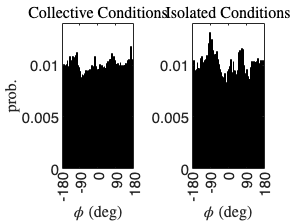

phi_collective_mat = cell2mat(phi_collective);
phi_collective_mat(isnan(phi_collective_mat)) = []; 

% collective setting 
figure
AX_phi(1) = subplot(1,2,1);
histogram(phi_collective_mat,100,'Normalization','probability')
title('Collective Conditions','Interpreter','latex')
xlim([-180, 180]);
xticks(-180:90:180);
xlabel('$\phi$ (deg)','Interpreter','latex')
ylabel('prob.','Interpreter','latex')

% isolated setting
phi_isolated_mat = cell2mat(phi_isolated);
phi_isolated_mat(isnan(phi_isolated_mat)) = []; 

AX_phi(2) = subplot(1,2,2);
histogram(phi_isolated_mat,100,'Normalization','probability')
title('Isolated Conditions','Interpreter','latex')
xlim([-180, 180]);
xticks(-180:90:180);
xlabel('$\phi$ (deg)','Interpreter','latex')

allYLim = get(AX_phi, {'YLim'});
allYLim = cat(2, allYLim{:});
set(AX_phi, 'YLim', [min(allYLim), max(allYLim)]);

`Check the isolated case again. It is a bit strange that it is not uniformly distributed across all the range. `


$$\psi \left(t\right):\textrm{orientation}$$


% collective setting 
vec_centrioid_head_collective = cell(size(row_worm_i_collective,1),1);
psi_collective = cell(size(row_worm_i_collective,1),1);
va = [1 0]; 
for i =1:size(worm_index_kept_collective,1)
    head = mean(skeleton_collective(1:2,1:16,row_worm_i_collective{i,1}),2);
    head = reshape(head,2,size(row_worm_i_collective{i},1))';
    vec_centrioid_head_collective{i,1} = head - dataFilt_collective{i};
    for j = 1:size(vec_centrioid_head_collective{i},1)
        vb = vec_centrioid_head_collective{i}(j,:)/sqrt(sum(vec_centrioid_head_collective{i}(j,:)).^2);
        psi_collective{i,1}(j,1) = atan2d(vb(1)*va(2)-vb(2)*va(1),vb(1)*va(1)+vb(2)*va(2));
        vb = []; 
    end 
end 

% isolated setting
vec_centrioid_head_isolated = cell(size(row_worm_i_isolated,1),1);
psi_isolated = cell(size(row_worm_i_isolated,1),1);
va = [1 0]; 
for i =1:size(worm_index_kept_isolated,1)
    head = mean(skeleton_isolated(1:2,1:16,row_worm_i_isolated{i,1}),2);
    head = reshape(head,2,size(row_worm_i_isolated{i},1))';
    vec_centrioid_head_isolated{i,1} = head - dataFilt_isolated{i};
    for j = 1:size(vec_centrioid_head_isolated{i},1)
        vb = vec_centrioid_head_isolated{i}(j,:)/sqrt(sum(vec_centrioid_head_isolated{i}(j,:)).^2);
        psi_isolated{i,1}(j,1) = atan2d(vb(1)*va(2)-vb(2)*va(1),vb(1)*va(1)+vb(2)*va(2));
        vb = []; 
    end 
end 

`Check angle distribution`

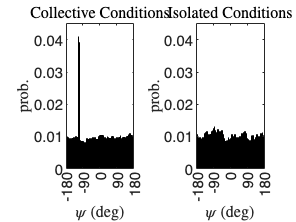

% collective setting 
psi_collective_mat = cell2mat(psi_collective);
psi_collective_mat(isnan(psi_collective_mat)) = []; 

figure
AX_psi(1) = subplot(1,2,1);
histogram(psi_collective_mat,100,'Normalization','probability')
xlim([-180, 180]);
xticks(-180:90:180);
xlabel('$\psi$ (deg)','Interpreter','latex')
ylabel('prob.','Interpreter','latex')
title('Collective Conditions','Interpreter','latex')

% isolated setting 
psi_isolated_mat = cell2mat(psi_isolated);
psi_isolated_mat(isnan(psi_isolated_mat)) = []; 

AX_psi(2) = subplot(1,2,2);
histogram(psi_isolated_mat,100,'Normalization','probability')
xlim([-180, 180]);
xticks(-180:90:180);
xlabel('$\psi$ (deg)','Interpreter','latex')
ylabel('prob.','Interpreter','latex')
title('Isolated Conditions','Interpreter','latex')

allYLim = get(AX_psi, {'YLim'});
allYLim = cat(2, allYLim{:});
set(AX_psi, 'YLim', [min(allYLim), max(allYLim)]);


$$\Delta \psi \left(t\right):\textrm{allignment}$$


% collective setting 
delta_psi_collective = cell(size(row_worm_i_collective,1),1);
for i =1:size(worm_index_kept_collective,1)
    delta_psi_collective{i} = (phi_collective{i} - psi_collective{i});
    for j =1:size(delta_psi_collective{i},1)   % ask greg if htis makes sense! not sure how to wrap between -90 and 270
        if delta_psi_collective{i}(j) < -90
            delta_psi_collective{i}(j) = abs(delta_psi_collective{i}(j)); 
        end 
        if delta_psi_collective{i}(j) > 270 
            delta_psi_collective{i}(j) = delta_psi_collective{i}(j) -360;
        end 
    end 
end 

delta_psi_collective_mat = cell2mat(delta_psi_collective);

% isolated setting 
delta_psi_isolated = cell(size(row_worm_i_isolated,1),1);
for i =1:size(worm_index_kept_isolated,1)
    delta_psi_isolated{i} = (phi_isolated{i} - psi_isolated{i});
    for j =1:size(delta_psi_isolated{i},1)   % ask greg if htis makes sense! not sure how to wrap between -90 and 270
        if delta_psi_isolated{i}(j) < -90
            delta_psi_isolated{i}(j) = abs(delta_psi_isolated{i}(j)); 
        end 
        if delta_psi_isolated{i}(j) > 270 
            delta_psi_isolated{i}(j) = delta_psi_isolated{i}(j) -360;
        end 
    end 
end 

delta_psi_isolated_mat = cell2mat(delta_psi_isolated);

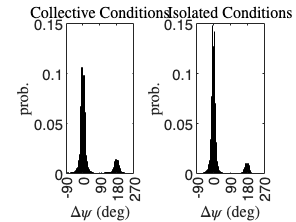

% collective setting 
figure
AX_delta_psi(1) = subplot(1,2,1);
histogram(delta_psi_collective_mat,100,'Normalization','probability')
xlim([-90, 270]);
xticks(-90:90:270);
xlabel('$\Delta \psi$ (deg)','Interpreter','latex')
ylabel('prob.','Interpreter','latex')
title('Collective Conditions','Interpreter','latex')

% isolated setting 
AX_delta_psi(2) = subplot(1,2,2);
histogram(delta_psi_isolated_mat,100,'Normalization','probability')
xlim([-90, 270]);
xticks(-90:90:270);
xlabel('$\Delta \psi$ (deg)','Interpreter','latex')
ylabel('prob.','Interpreter','latex')
title('Isolated Conditions','Interpreter','latex')

allYLim = get(AX_delta_psi, {'YLim'});
allYLim = cat(2, allYLim{:});
set(AX_delta_psi, 'YLim', [min(allYLim), max(allYLim)]);

`Quantification of differencw between distrbutions`

`Kullback-Leiber divergence `

delta_psi_total = [delta_psi_collective_mat; delta_psi_isolated_mat];
labels = logical([zeros(size(delta_psi_collective_mat,1),1); ones(size(delta_psi_isolated_mat,1),1)]);
D_KL = relativeEntropy(delta_psi_total, labels)

D_KL = single
0.1707

# Loop through all strains and compute distributions

% cd('..');
% cd '/Users/erusconi/Desktop/Brighfield_40&5/Collective(40_worms)/Results/skeletons'
% fds = fileDatastore('*.hdf5', 'ReadFcn', @importdata);   % here you can specify which ever file type you prefer 
% 
% skelFile = fds.Files;
% 
% numFiles = length(skelFile);
% 
% 
% for k = 1 : numFiles
%     name = sprintf('dataSet_%d', k);   
% 
%     trajData_collective.(name) = h5read(skelFile{k},'/trajectories_data');
%     skeleton_collective.(name)= h5read(skelFile{k}, '/skeleton');
% end 
% 
% cd('..');
% cd '/Users/erusconi/Desktop/Brighfield_40&5/Isolated(5_Worms)/Results/skeletons'
% fds = fileDatastore('*.hdf5', 'ReadFcn', @importdata);   % here you can specify which ever file type you prefer 
% 
% skelFile = fds.Files;
% 
% numFiles = length(skelFile);
% 
% 
% for k = 1 : numFiles
%     name = sprintf('dataSet_%d', k);   
% 
%     trajData_isolated.(name) = h5read(skelFile{k},'/trajectories_data');
%     skeleton_isolated.(name)= h5read(skelFile{k}, '/skeleton');
% end 